# 2 - Lancamento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1)

## a) probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos

n = 20;
m = 100;
N = 1e5;

alvos = randi([1,m],n, N); % 20 tentativas por coluna
sum = 0;
for a = 1:N
    if length(unique(alvos(:,a))) == n
        sum = sum + 1;
    end
end
fprintf("A) %.f%%", sum / N * 100);

A) 13%

## b) a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos

fprintf("B) %.f%%", (1 - sum / N) * 100);

B) 87%

## c) m = 1000 e m = 100000 alvos. Para cada um destes valores, faca as simulacoes necessarias para desenhar um grafico (usando a funcao plot do Matlab) da probabilidade da alinea (b) em funcao do numero de dardos n. Considere n de 10 a 100 com incrementos de 10. Os 2 graficos devem ser sub-graficos de uma mesma figura (use a instrucao subplot do Matlab)

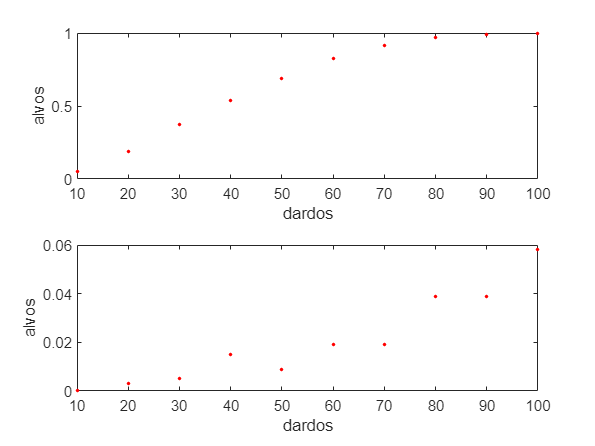

n = 10:10:100;
m = [1e3 1e5];
N = 1e3;

for k=1:2
  subplot(2,1,k);
  probs = 0*n;
  for i=1:length(n)
    probs(i) =  1 - alvo(n(i), N, m(k));
  end
  
  plot(n(1:i),probs(1:i),"r.");
  xlabel('dardos');
  ylabel('alvos');
end

## d) n = 100 dardos. Faca as simulacoes necessarias para desenhar um grafico da probabilidade da alinea (b) em funcao dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos

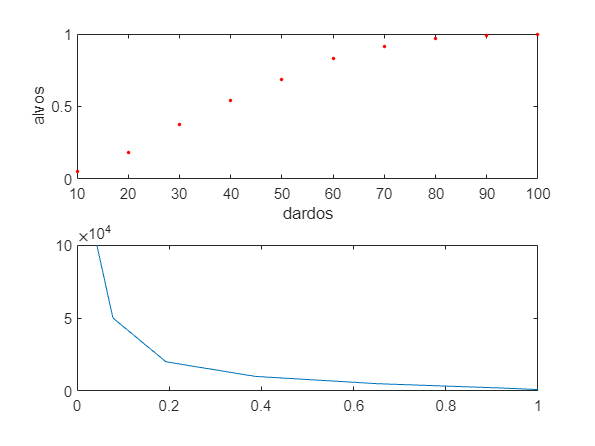

n = 100;
m = [2e2 5e2 1e3 2e3 5e3 1e4 2e4 5e4 1e5];
N = 1e3;
prob = [];

for i=1:length(m)
    prob(i) =  1 - alvo(n, N, m(i));
end
 plot(prob, m)